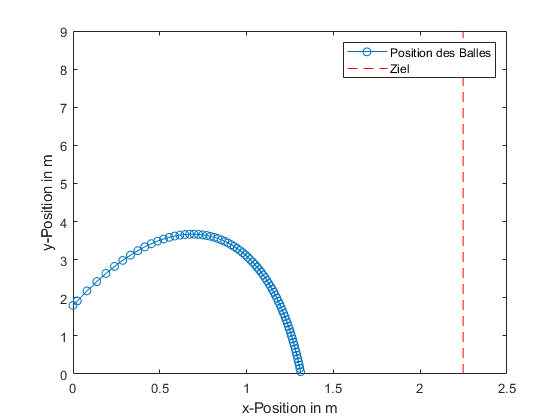

clc
clear all

% parameteranalyse
% function from main must be seperate function file!!!

run main.mlx



%varying alpha_0
figure(2)

alpha_vary= alpha_0-10*pi/180:5*pi/180:alpha_0+10*pi/180;
for index = 1:length(alpha_vary)
    
    v_0x = v_0*cos(alpha_vary(index));
    v_0y = v_0*sin(alpha_vary(index));
   
   f1=[x0; y0; v_0x; v_0y];  % Anfangsbedingungen für x, y, v_x, v_y 


    sol = ode45(@(t,y) equations(t,y,par), tspan, f1, options);
    plot(sol.x,sol.y(2,:));
    hold on
end

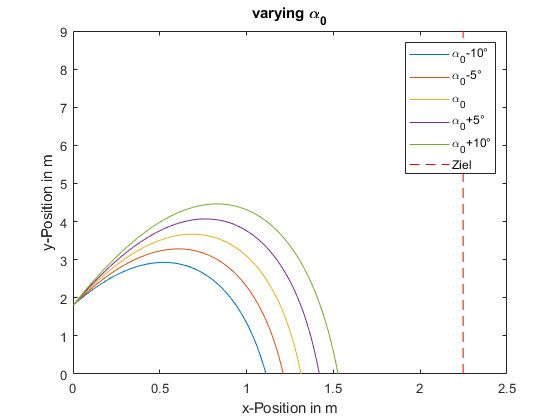


ylim([0 5*y0])
xlabel('x-Position in m')
ylabel('y-Position in m')
s_l = par.l + par.s_Becher + (3/2)*par.d_Becher;    % Mittlerer Becher als Ziel
l = line([s_l s_l],[0 5*y0],'Color','red','LineStyle','--');
legend('\alpha_0-10°','\alpha_0-5°','\alpha_0','\alpha_0+5°','\alpha_0+10°', 'Ziel')
title("varying \alpha_0")
hold off



%varying v0
figure(2)

v_vary= v_0-1 :0.5 : v_0+1;
for index = 1:length(v_vary)
    
    v_0x = v_vary(index)*cos(alpha_0);
    v_0y = v_vary(index)*sin(alpha_0);
   
   f1=[x0; y0; v_0x; v_0y];  % Anfangsbedingungen für x, y, v_x, v_y 


    sol = ode45(@(t,y) equations(t,y,par), tspan, f1, options);
    plot(sol.x,sol.y(2,:));
    hold on
end

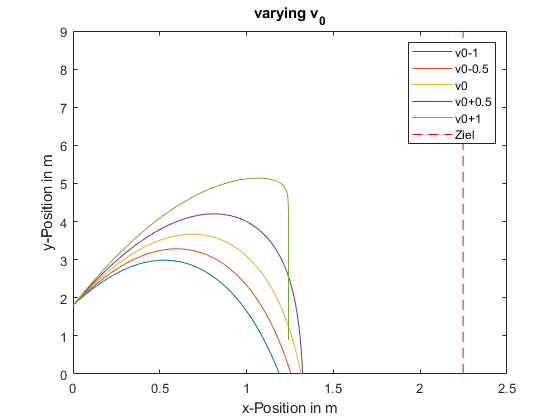

ylim([0 5*y0])
xlabel('x-Position in m')
ylabel('y-Position in m')
s_l = par.l + par.s_Becher + (3/2)*par.d_Becher;    % Mittlerer Becher als Ziel
l = line([s_l s_l],[0 5*y0],'Color','red','LineStyle','--');
legend('v0-1','v0-0.5','v0', 'v0+0.5','v0+1','Ziel')
title("varying v_0")
hold off